# Lab 3 – Frequency-Domain Filtering with fft2

Course: Mathematical Algorithms (DSP)

**Lecture: 9 – Image Processing LabsObjective**

The objective of this lab is to understand how digital images can be analyzed and filtered in the frequency domain using MATLAB.

The experiments include visualizing the Fourier magnitude spectrum, applying ideal and Gaussian low-pass filters, performing high-pass filtering, and comparing spatial-domain and frequency-domain filtering.

The lab also explores the relationship between spatial convolution and frequency-domain multiplication.

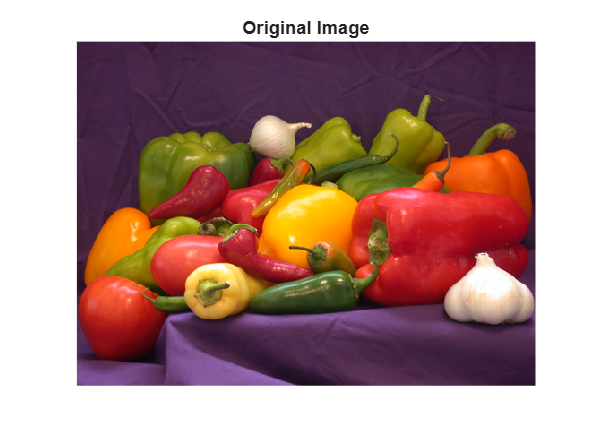


%% Lab 3: Frequency-Domain Filtering with fft2
% Section 0: Load and Prepare the Image

close all;
clear;
clc;

% Load the sample image
if exist('peppers.png', 'file')
    I0 = imread('peppers.png');
else
    I0 = repmat(imread('cameraman.tif'), 1, 1, 3);
end

% Convert to grayscale and double precision
I = im2double(rgb2gray(I0));

% Get image dimensions
[M, N] = size(I);

% Display original and grayscale images
figure;
imshow(I0);
title('Original Image');

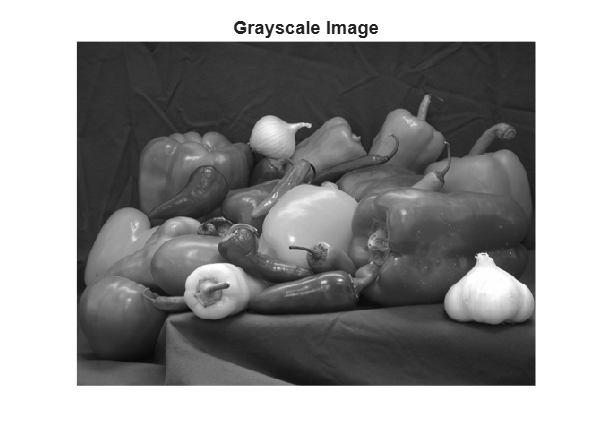


figure;
imshow(I);
title('Grayscale Image');


% Display image information
fprintf('Image size: %d x %d\n', M, N);

Image size: 384 x 512


fprintf('Data type: %s\n', class(I));

Data type: double


fprintf('Intensity range: %.3f to %.3f\n', ...
    min(I(:)), max(I(:)));

Intensity range: 0.031 to 1.000


**Section 0 – Image Preparation**

The image was loaded into MATLAB and converted from RGB to grayscale.

The grayscale image was then converted to double precision using `im2double`, representing pixel intensities between 0 and 1.

The image dimensions were obtained using the `size` function.

This preparation allows the two-dimensional Fourier transform to be applied to the image for frequency-domain analysis and filtering.

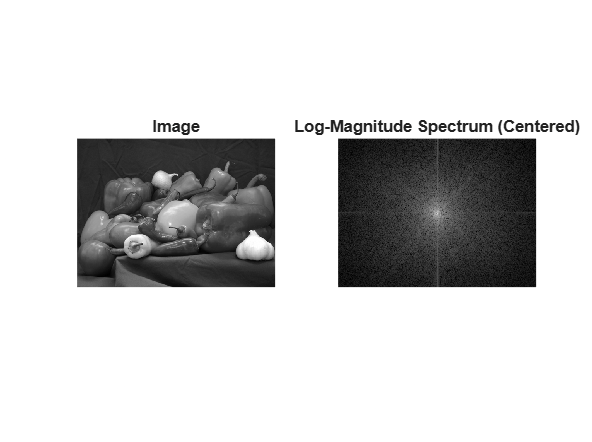


%% 1) Magnitude Spectrum (Log-Scale)

% Calculate the 2D Fourier Transform
F = fft2(I);

% Shift zero frequency to the center
Fshift = fftshift(F);

% Calculate log-magnitude spectrum
S = log(1 + abs(Fshift));

% Display image and frequency spectrum
figure;

subplot(1,2,1);
imshow(I, []);
title('Image');

subplot(1,2,2);
imshow(S, []);
title('Log-Magnitude Spectrum (Centered)');

**Section 1 – Magnitude Spectrum (Log-Scale)**

The two-dimensional Fast Fourier Transform was applied to the grayscale image using the `fft2` function.

The `fftshift` function was used to move the zero-frequency component to the center of the spectrum, making the frequency distribution easier to interpret.

The magnitude spectrum was calculated using the absolute value of the Fourier coefficients. A logarithmic transformation was then applied to improve the visibility of frequency components with smaller magnitudes.

The center of the spectrum represents low spatial frequencies, which correspond to gradual intensity changes in the image. Higher spatial frequencies are located farther from the center and are associated with fine details, textures, and sharp edges.

This experiment demonstrates how an image can be analyzed as a two-dimensional signal in the frequency domain.

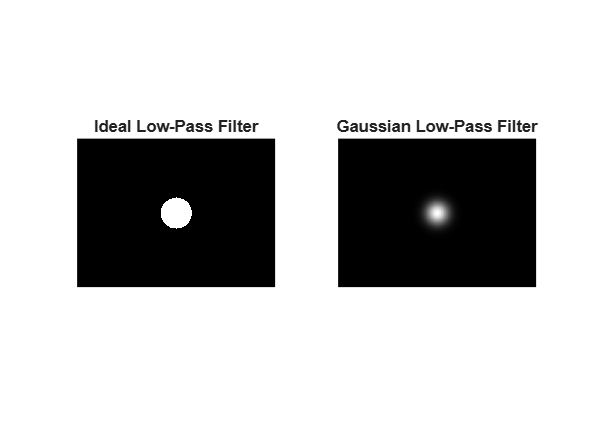


%% 2) Ideal & Gaussian Low-Pass in Frequency

% Create the frequency coordinate grid
[u,v] = meshgrid( ...
    -floor(N/2):(ceil(N/2)-1), ...
    -floor(M/2):(ceil(M/2)-1));

% Calculate distance from the center
D = sqrt(u.^2 + v.^2);

% Ideal low-pass filter
D0 = 40; % Cutoff radius
H_ideal_LP = double(D <= D0);

% Gaussian low-pass filter
sigma = 20;
H_gauss_LP = exp(-(D.^2) / (2*sigma^2));

% Display both frequency-domain filters
figure;

subplot(1,2,1);
imshow(H_ideal_LP, []);
title('Ideal Low-Pass Filter');

subplot(1,2,2);
imshow(H_gauss_LP, []);
title('Gaussian Low-Pass Filter');

**Section 2 – Ideal and Gaussian Low-Pass Filters**

Two low-pass filters were created in the frequency domain: an ideal low-pass filter and a Gaussian low-pass filter.

A frequency coordinate grid was generated, and the distance of each frequency point from the center was calculated.

The ideal low-pass filter used a cutoff radius of 40. It allows frequencies inside the circular region to pass while blocking frequencies outside it.

The Gaussian low-pass filter used a sigma value of 20. Unlike the ideal filter, it gradually reduces higher-frequency components without a sharp cutoff.

The main difference is that the ideal filter has an abrupt transition, while the Gaussian filter provides smoother frequency attenuation. This affects the amount of ringing and smoothing when the filters are applied to an image.

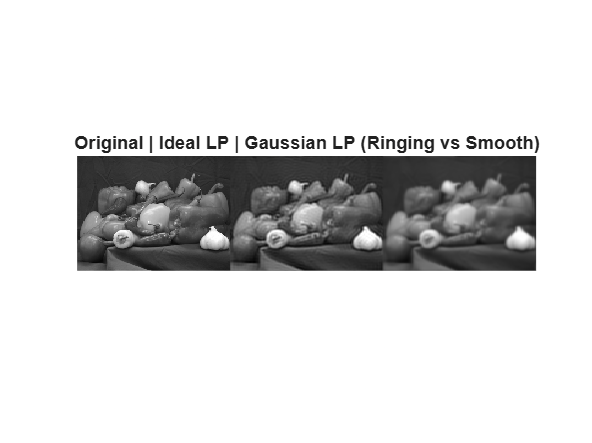


%% 3) Apply LP Filters in Frequency Domain

% Apply ideal low-pass filter
G_ideal = ifft2(ifftshift(H_ideal_LP .* Fshift));

% Apply Gaussian low-pass filter
G_gauss = ifft2(ifftshift(H_gauss_LP .* Fshift));

% Display comparison
figure;
montage({I, real(G_ideal), real(G_gauss)}, 'Size', [1 3]);

title('Original | Ideal LP | Gaussian LP (Ringing vs Smooth)');

**Section 3 – Applying Low-Pass Filters in the Frequency Domain**

The ideal and Gaussian low-pass filters created in Section 2 were applied to the Fourier transform of the grayscale image.

Each filter was multiplied by the centered frequency spectrum. The inverse Fourier transform was then used to reconstruct the filtered images in the spatial domain.

The ideal low-pass filter removes frequency components outside a fixed cutoff radius. This reduces high-frequency image details but can also introduce ringing artifacts near sharp intensity transitions because of the abrupt frequency cutoff.

The Gaussian low-pass filter gradually attenuates high-frequency components, producing smoother blurring with less tendency toward ringing.

This experiment demonstrates how the frequency response of a filter affects the appearance of the reconstructed image.

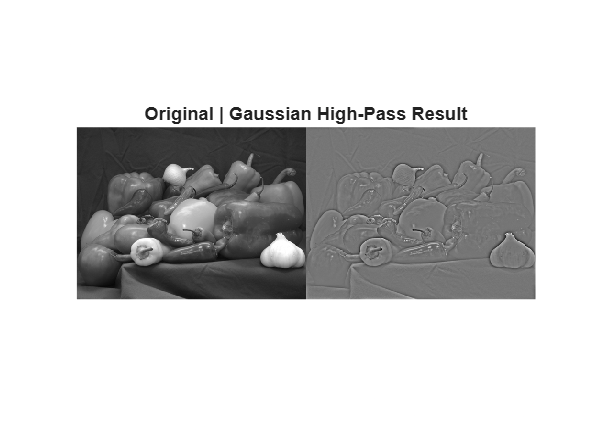


%% 4) High-Pass via Complement

% Create Gaussian high-pass filter
H_gauss_HP = 1 - H_gauss_LP;

% Apply high-pass filter in frequency domain
G_hp = real(ifft2(ifftshift(H_gauss_HP .* Fshift)));

% Normalize result for display
G_hp = mat2gray(G_hp);

% Display original and high-pass filtered images
figure;
montage({I, G_hp}, 'Size', [1 2]);

title('Original | Gaussian High-Pass Result');

**Section 4 – Gaussian High-Pass Filtering**

A Gaussian high-pass filter was created by subtracting the Gaussian low-pass filter from 1.

This filter suppresses low-frequency components, which represent gradual intensity variations, while retaining higher-frequency components associated with edges, textures, and fine details.

The high-pass filter was multiplied by the Fourier transform of the image, and the inverse Fourier transform was used to reconstruct the filtered result.

The resulting image was normalized using `mat2gray` to improve its visibility.

Compared with the original image, the high-pass filtered result emphasizes rapid intensity changes and reduces smooth image regions. This demonstrates how frequency-domain filtering can be used to extract image details.

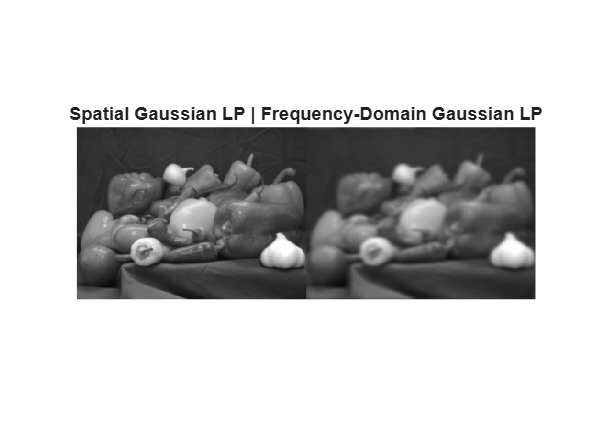


%% 5) Compare Spatial vs Frequency-Domain Gaussian LP

% Create a 1D Gaussian filter
g1d = fspecial('gaussian', [1 7], 1.2);

% Apply a 2D Gaussian filter in the spatial domain
I_spatial_gauss = imfilter(I, g1d' * g1d, 'replicate');

% Display spatial and frequency-domain results
figure;
montage({I_spatial_gauss, real(G_gauss)}, 'Size', [1 2]);

title('Spatial Gaussian LP | Frequency-Domain Gaussian LP');

**Section 5 – Spatial vs Frequency-Domain Gaussian Filtering**

Gaussian low-pass filtering was performed using two methods: spatial-domain filtering and frequency-domain filtering.

In the spatial domain, a 7×7 Gaussian kernel with a standard deviation of 1.2 was created and applied using `imfilter`.

In the frequency domain, the Gaussian filter created earlier with a frequency-domain sigma value of 20 was applied using Fourier multiplication and the inverse Fourier transform.

Both methods reduce high-frequency information and smooth the image. However, the filtering parameters are not equivalent, so the resulting images may show different amounts of blurring.

Another difference is the boundary handling. The spatial filter uses replicated image borders, while the FFT-based method assumes periodic boundaries.

This experiment demonstrates that Gaussian smoothing can be implemented in both domains. To obtain closely matching numerical results, equivalent filter kernels and consistent boundary handling are required.

## Section 6 – Reflections

**1. Why does ideal low-pass filtering cause ringing (Gibbs phenomenon)?**

Ideal low-pass filtering causes ringing because it uses a sharp cutoff in the frequency domain. Frequencies below the cutoff are kept, while frequencies above it are completely removed.

This sudden change produces an oscillating response in the spatial domain. As a result, unwanted bright and dark patterns can appear around sharp edges in the image.

This effect is related to the Gibbs phenomenon. Gaussian filtering reduces this problem because it removes high frequencies gradually instead of using an abrupt cutoff.

**2. What does **`fftshift`** do visually?**

The `fftshift` function moves the zero-frequency component from the corners of the Fourier spectrum to the center.

This makes the spectrum easier to understand because low frequencies appear near the center, while higher frequencies are located farther away.

Without `fftshift`, the frequency spectrum is harder to interpret visually because the low-frequency components are distributed around the corners.

**3. When is frequency-domain filtering computationally preferable?**

Frequency-domain filtering is often preferable when working with large images and large convolution kernels.

In spatial-domain filtering, the number of calculations increases with the size of the filter kernel. Frequency-domain filtering uses the Fast Fourier Transform (FFT), which can make large filtering operations more efficient.

However, spatial-domain filtering is often simpler and faster for small kernels because it does not require Fourier transforms.

Frequency-domain filtering is especially useful for large filters, repeated filtering operations, and applications that require direct control over frequency components.

## Conclusion

In this lab, I explored image processing in the frequency domain using MATLAB.

I used `fft2` and `fftshift` to visualize the Fourier magnitude spectrum of an image. I then created ideal and Gaussian low-pass filters to study how different frequency responses affect image smoothing.

The ideal low-pass filter demonstrated the possibility of ringing artifacts, while the Gaussian low-pass filter provided smoother frequency attenuation.

I also applied a Gaussian high-pass filter to emphasize edges and fine image details.

Finally, I compared spatial-domain and frequency-domain Gaussian filtering and learned that equivalent filter parameters and consistent boundary handling are important when comparing the results.

In general, this lab helped me understand the relationship between spatial-domain filtering and frequency-domain multiplication.